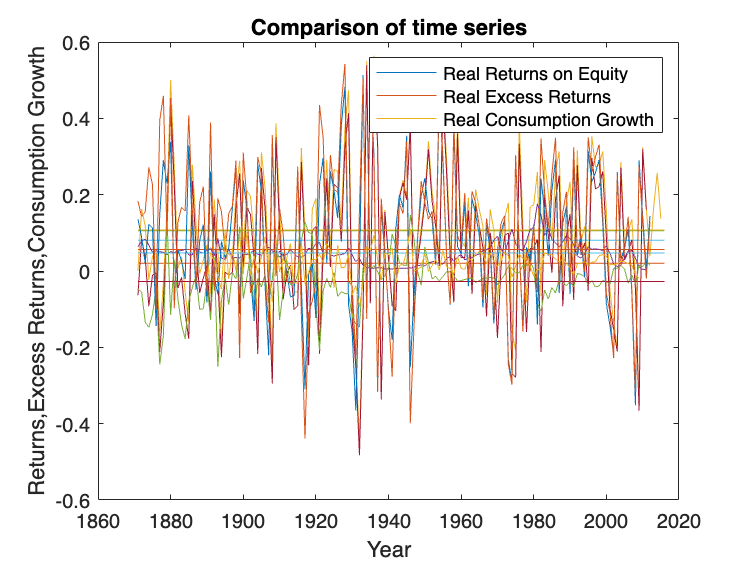

clear all
clc

%% Data Import
data=xlsread('chapt26.xlsx','A9:U154');
year=data(:,1);             % date
real_r=data(:,16);          % real returns
cpi=data(:,7);              % CPI index to account for inflation
nom_price=data(:,2);        % nominal price of index
nom_div=data(:,3);          % nominal dividend of index
real_1y_int=1-data(:,8);    % real 1-year risk free rate
nom_1y_int=data(:,5)/100;   % nominal 1-year risk free rate
real_cons=data(:,9);        % real consumption

%% Calculation of nominal returns
nom_r=zeros(146,1);

for i=1:145
nom_r(i+1)=(nom_price(i+1)+nom_div(i+1)-nom_price(i))/nom_price(i);
end

%% 1) mean and volatility of nominal returns of the whole sample and of post WW2 sample
mu_nom_r=nanmean(nom_r(2:end));
mu_nom_r_postww2=nanmean(nom_r(75:end));
sigma_nom_r=nanstd(nom_r);
sigma_nom_r_postww2=nanstd(nom_r(75:end));


%% 2) mean and volatility of real returns of the whole sample and of post WW2 sample
mu_real_r=nanmean(real_r);
mu_real_r_postww2=nanmean(real_r(75:end));
sigma_real_r=nanstd(real_r);
sigma_real_r_postww2=nanstd(real_r(75:end));

%% 3) mean and volatility of real 1-year interest rate
mu_real_1y_int=nanmean(real_1y_int);
sigma_real_1y_int=nanstd(real_1y_int);

%% Calculation of excess nominal and real returns
excess_nom=nom_r-nom_1y_int;
excess_real=real_r-real_1y_int;

%% 4) mean of excess nominal and real return of whole sample and of post WW2 sample
mu_excess_nom=nanmean(excess_nom);
mu_excess_nom_postww2=nanmean(excess_nom(75:end));

mu_excess_real=nanmean(excess_real);
mu_excess_real_postww2=nanmean(excess_real(75:end));

%% Calculation of real consumption growth
real_cons_growth=zeros(146,1);

for i=1:145
real_cons_growth(i+1)=(real_cons(i+1)-real_cons(i))/real_cons(i);
end

%% 5) mean and volatility of real consumption growth
mu_cons_growth=nanmean(real_cons_growth);
sigma_cons_growth=nanstd(real_cons_growth);

%% 6) correlation matrix of real returns, excess real returns, real consumption growth
ret_ex_cons=[real_r excess_real real_cons_growth];
corr_ret_ex_cons=corr(ret_ex_cons(20:139,:));

%% plots

mu_real_cons_growth_vector=ones(size(real_cons_growth));
mu_real_cons_growth_vector=mu_real_cons_growth_vector*mu_cons_growth;
figure(1)
plot(year,real_cons_growth)
hold on
plot(year,mu_real_cons_growth_vector)
title('Real Consumption Growth')
xlabel('Year')
ylabel('Real Consumption Growth')
legend({'Real Consumption Growth','Mean'},'Location','northeast')

mu_nom_r_vector=ones(size(nom_r));
mu_nom_r_vector=mu_nom_r_vector*mu_nom_r;
mu_real_r_vector=ones(size(real_r));
mu_real_r_vector=mu_real_r_vector*mu_real_r;
figure (2)
plot(year,nom_r)
hold on
plot(year,real_r)
hold on
plot(year,mu_nom_r_vector);
hold on
plot(year,mu_real_r_vector);
title('Equity Returns')
xlabel('Year')
ylabel('Returns')
legend({'Nominal','Real','Nominal Mean','Real Mean'},'Location','northeast')

mu_excess_real_vector=ones(size(excess_real));
mu_excess_real_vector=mu_excess_real_vector*mu_excess_real;
mu_excess_nom_vector=ones(size(excess_nom));
mu_excess_nom_vector=mu_excess_nom_vector*mu_excess_nom;
figure(3)
plot(year,excess_nom)
hold on
plot(year,excess_real)
hold on
plot(year,mu_excess_nom_vector)
hold on
plot(year,mu_excess_real_vector);
title('Excess Returns')
xlabel('Year')
ylabel('Excess Returns')
legend({'Nominal','Real','Nominal Mean','Real Mean'},'Location','northeast')

mu_nom_1y_int=nanmean(nom_1y_int);
mu_nom_1y_vector=ones(size(nom_1y_int));
mu_nom_1y_vector=mu_nom_1y_vector*mu_nom_1y_int;
mu_real_1y_vector=ones(size(real_1y_int));
mu_real_1y_vector=mu_real_1y_vector*mu_real_1y_int;
figure(4)
plot(year,nom_1y_int)
hold on
plot(year,real_1y_int)
hold on
plot(year,mu_nom_1y_vector);
hold on
plot(year,mu_real_1y_vector);
title('1-year Interest Rate')
xlabel('Year')
ylabel('1-year Interest Rate')
legend({'Nominal','Real','Nominal Mean','Real Mean'},'Location','northeast')

figure(5)
plot(year,real_r)
hold on
plot(year,excess_real)
hold on
plot(year,real_cons_growth)
title('Comparison of time series')
xlabel('Year')
ylabel('Returns,Excess Returns,Consumption Growth')
legend({'Real Returns on Equity','Real Excess Returns','Real Consumption Growth'},'Location','northeast')